%%%%%% 1
alpha =1;
clear all;
fc = 10;
fs= 20;
Fs = 720;
Wc = fc/(Fs/2);
Ws = fs/(Fs/2);

[N,Wn] = buttord(Wc,Ws,1,40);

[b,a] = butter(N,Wn);
T_F= tf(b,a,1/Fs)

T_F =
 
  2.668e-11 z^8 + 2.134e-10 z^7 + 7.47e-10 z^6 + 1.494e-09 z^5 + 1.867e-09 z^4 + 1.494e-09 z^3 + 7.47e-10 z^2 + 2.134e-10 z + 2.668e-11
  -------------------------------------------------------------------------------------------------------------------------------------
                      z^8 - 7.496 z^7 + 24.6 z^6 - 46.15 z^5 + 54.15 z^4 - 40.69 z^3 + 19.12 z^2 - 5.136 z + 0.604
 
Sample time: 0.0013889 seconds
Discrete-time transfer function.


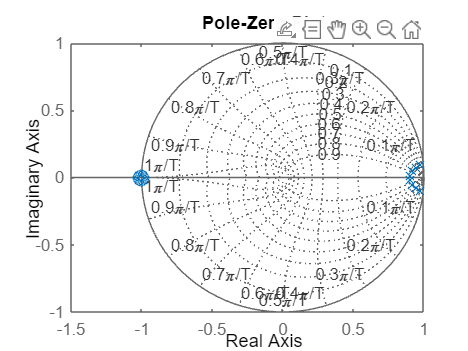

figure
pzmap(T_F)
title('Pole-Zero Plot');
grid on

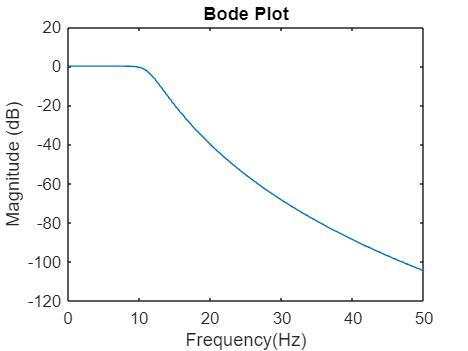


f=linspace(0,50,100);
figure;
[mag, phase ]= bode(T_F,2*pi*f);
plot(f,db(squeeze(mag)))
title('Bode Plot');
xlabel("Frequency(Hz)");
ylabel("Magnitude (dB)");

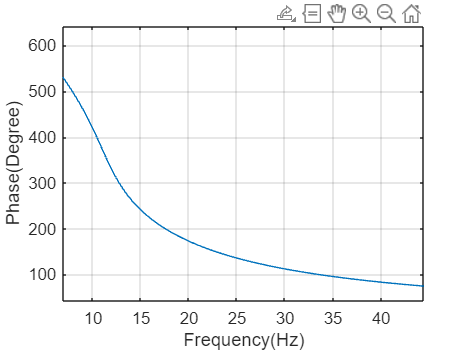

plot(f,squeeze(phase))
xlabel("Frequency(Hz)");
ylabel("Phase(Degree)");
grid on

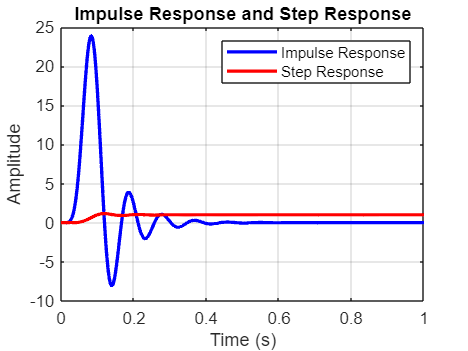




% Define the time vector for 1 second
t = 0:1/Fs:1;
impulse_response = impulse(T_F, t);
step_response = step(T_F, t);

figure;
plot(t, impulse_response, 'b', 'LineWidth', 2, 'DisplayName', 'Impulse Response');
hold on;
plot(t, step_response, 'r', 'LineWidth', 2, 'DisplayName', 'Step Response');
xlabel('Time (s)');
ylabel('Amplitude');
title('Impulse Response and Step Response');
legend('show');
grid on;

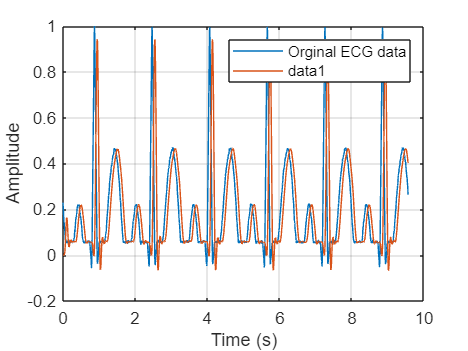

%%%%%%% 2
ecg_signal = load('ECG_Data.txt');
filtered_signal = filter(b,a,ecg_signal);

t = (0:length(ecg_signal)-1) / Fs;

% Plot the original and filtered ECG signals
figure;
plot(t, ecg_signal);
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
legend("Orginal ECG data");

hold on;
plot(t, filtered_signal);

xlabel('Time (s)');
ylabel('Amplitude');

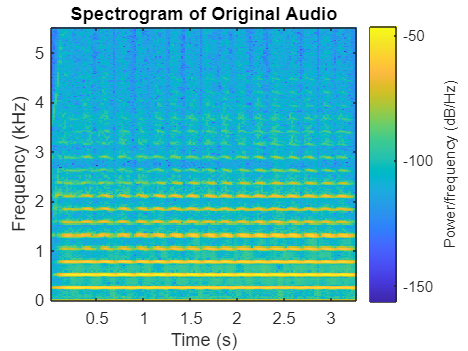

%%%%%%% 3
[y, Fs] = audioread('instru1.wav');

figure;
spectrogram(y, hamming(500), 250, 500, Fs, 'yaxis');
title('Spectrogram of Original Audio');

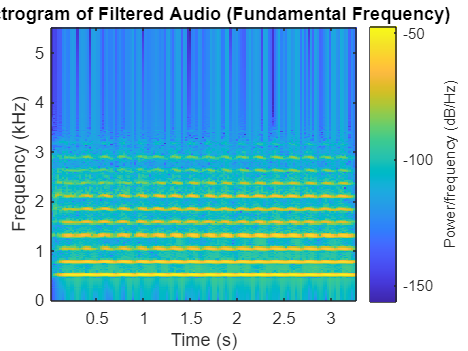


% Design a Butterworth band-pass filter
order = 10; % Filter order
Fc1 = 500; % Lower cutoff frequency in Hz
Fc2 = 3000; % Upper cutoff frequency in Hz

% Normalize cutoff frequencies
Wn1 = Fc1 / (Fs/2);
Wn2 = Fc2 / (Fs/2);

% Design the filter
[b, a] = butter(order, [Wn1, Wn2], 'bandpass');

% Apply the filter to the audio signal
filtered_signal = filter(b, a, y);

% Write the filtered signal to a new WAV file
audiowrite('filtered_audio.wav', filtered_signal, Fs);
[Y,q ]= audioread("filtered_audio.wav");
sound(Y,q)

% Plot the spectrogram of the filtered signal
figure;
spectrogram(filtered_signal, hamming(500), 250, 500, Fs, 'yaxis');
title('Spectrogram of Filtered Audio (Fundamental Frequency)');

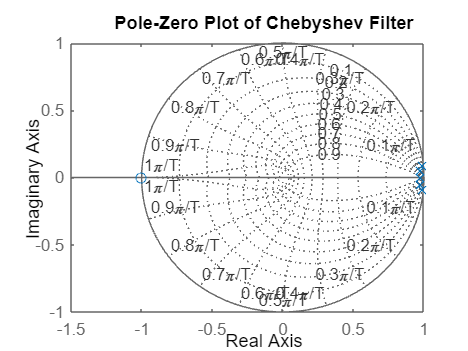

%prob_4
% Given parameters
alpha = 1;           % Maximum passband ripple in dB
stopband = 40; % Minimum stopband attenuation in dB
Fs = 720;            % Sampling frequency in samples/sec
Fp = 10;             % Passband edge frequency in Hz
Fstop = 20;          % Stopband edge frequency in Hz

% Calculate normalized cutoff frequencies (Wc and Ws)
Wc = 2 * Fp / Fs;
Ws = 2 * Fstop / Fs;

% Determine filter order (N) using the formula for Chebyshev Type I filter
[n, Wn] = cheb1ord(Wc, Ws, alpha, stopband);

% Design the Chebyshev Type I filter
[z, p] = cheby1(n, alpha, Wn);
chebyshev = tf(z, p, 1/Fs);
figure
pzmap(chebyshev)
grid on
title('Pole-Zero Plot of Chebyshev Filter');


% Design the Butterworth filter as in the previous example
[n_butterworth, Wn_butterworth] = buttord(Wc, Ws, alpha, stopband);
[z_butterworth, p_butterworth] = butter(n_butterworth, Wn_butterworth);
butterworth = tf(z_butterworth, p_butterworth, 1/Fs);

% Compare the filter orders
fprintf('Chebyshev Type I Filter Order: %d\n', n);

Chebyshev Type I Filter Order: 5


fprintf('Butterworth Filter Order: %d\n', n_butterworth);

Butterworth Filter Order: 8


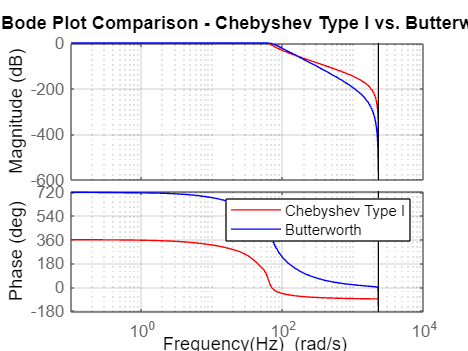


% Plot the Bode plots of Chebyshev Type I and Butterworth filters
figure;
bode(chebyshev, 'r', butterworth, 'b');
title('Bode Plot Comparison - Chebyshev Type I vs. Butterworth');
legend('Chebyshev Type I', 'Butterworth');
xlabel("Frequency(Hz)")

grid on;

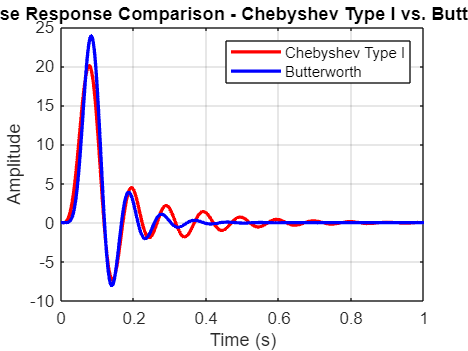


% Define the time vector for 1 second
t = 0:1/Fs:1;

% Compute the impulse response of the Chebyshev Type I filter
impulse_response_chebyshev = impulse(chebyshev, t);

% Compute the step response of the Chebyshev Type I filter
step_response_chebyshev = step(chebyshev, t);

% Compute the impulse response and step response of the Butterworth filter
impulse_response_butterworth = impulse(butterworth, t);
step_response_butterworth = step(butterworth, t);

% Plot the impulse response and step response of both filters on the same graph
figure;
plot(t, impulse_response_chebyshev, 'r', 'LineWidth', 2, 'DisplayName', 'Chebyshev Type I');
hold on;
plot(t, impulse_response_butterworth, 'b', 'LineWidth', 2, 'DisplayName', 'Butterworth');
xlabel('Time (s)');
ylabel('Amplitude');
title('Impulse Response Comparison - Chebyshev Type I vs. Butterworth');
legend('Location', 'northeast');
grid on;

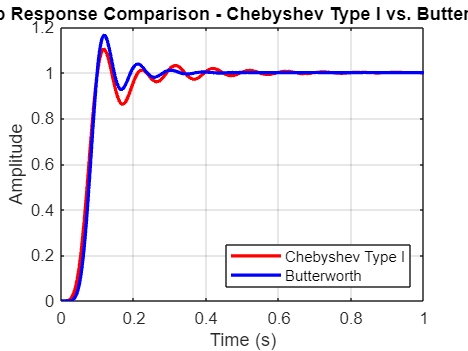


figure;
plot(t, step_response_chebyshev, 'r', 'LineWidth', 2, 'DisplayName', 'Chebyshev Type I');
hold on;
plot(t, step_response_butterworth, 'b', 'LineWidth', 2, 'DisplayName', 'Butterworth');
xlabel('Time (s)');
ylabel('Amplitude');
title('Step Response Comparison - Chebyshev Type I vs. Butterworth');
legend('Location', 'southeast');
grid on;